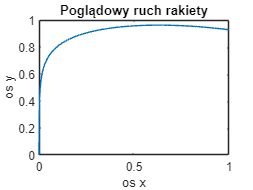


n = 1000;    % Ilość próbek
x0 = 0;     % Początek osi x
xe = 1;     % Koniec osi x
x= linspace(x0,xe, n);
y = (log10(6*x)+3.3)/3.805 - (6*x).^2/250;
y(1) = 0;
plot(x,y)
title("Poglądowy ruch rakiety")
xlabel("os x")
ylabel("os y")


% Parametry silników //////////
% Ilość kroków na pełny obrót
engine_rot = 200;
engine_up = 200;
% Przekładnia silnika
e_rot = 2;
e_up = 4;
% Przekładnia taśmy dla silnika up
e_up_2 = 10;
engine_multiplier_rot = engine_rot * e_rot;
engine_multiplier_up = engine_up * e_up * e_up_2;
% /////////////////////////////

dx = (xe-x0)/n;
dy = ((log10(6*(x+dx))+3.3)./3.805 - (6*(x+dx).^2/250)) - y;
cosA = dx./dy

cosA =     0.0035    0.0126    0.0216    0.0305    0.0393    0.0481    0.0569    0.0657    0.0744    0.0832    0.0919    0.1006    0.1094    0.1181    0.1267    0.1354    0.1440    0.1526    0.1612    0.1697    0.1782    0.1867    0.1951    0.2034    0.2117    0.2200    0.2281    0.2362    0.2442    0.2522    0.2600    0.2678    0.2755    0.2830    0.2905    0.2978    0.3050    0.3121    0.3191    0.3260    0.3327    0.3392    0.3456    0.3519    0.3580    0.3640    0.3698    0.3754    0.3808    0.3861


kat = acosd(cosA)

kat =    89.7978   89.2752   88.7608   88.2533   87.7479   87.2435   86.7395   86.2358   85.7324   85.2292   84.7262   84.2236   83.7214   83.2197   82.7186   82.2182   81.7187   81.2202   80.7230   80.2271   79.7329   79.2404   78.7499   78.2616   77.7759   77.2928   76.8127   76.3359   75.8626   75.3932   74.9278   74.4669   74.0107   73.5595   73.1137   72.6735   72.2394   71.8116   71.3904   70.9762   70.5693   70.1700   69.7787   69.3957   69.0211   68.6555   68.2990   67.9520   67.6146   67.2873


kat = kat-90

kat =    -0.2022   -0.7248   -1.2392   -1.7467   -2.2521   -2.7565   -3.2605   -3.7642   -4.2676   -4.7708   -5.2738   -5.7764   -6.2786   -6.7803   -7.2814   -7.7818   -8.2813   -8.7798   -9.2770   -9.7729  -10.2671  -10.7596  -11.2501  -11.7384  -12.2241  -12.7072  -13.1873  -13.6641  -14.1374  -14.6068  -15.0722  -15.5331  -15.9893  -16.4405  -16.8863  -17.3265  -17.7606  -18.1884  -18.6096  -19.0238  -19.4307  -19.8300  -20.2213  -20.6043  -20.9789  -21.3445  -21.7010  -22.0480  -22.3854  -22.7127


kat(1)=0;

% inny sposób

list_x = x;

stepper_motor_list_1=1:n;
list=list_x;
for i=1:(n-1)
    stepper_motor_list_1(i) = 0;
    while list(i)>=1
        stepper_motor_list_1(i)=stepper_motor_list_1(i)+1;
        list(i) = list(i)-1;
    end
    while list(i)<=-1
        stepper_motor_list_1(i)=stepper_motor_list_1(i)-1;
        list(i) = list(i)+1;
    end
    list(i+1) = list(i+1)+list(i);
end
stepper_motor_list_1(n) = 0;
stepper_motor_list_1

stepper_motor_list_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0


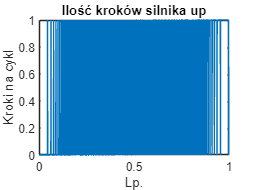

plot(x,stepper_motor_list_1)
title("Ilość kroków silnika up")
xlabel("Lp.")
ylabel("Kroki na cykl")


% /////
% Suma wszystkich kątów dla silnika ROT (z błędem)
suma=0;
for v=1:n
    suma = suma+kat(v);
end
suma

suma = -5.5041e+03

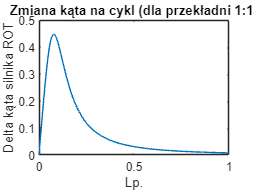

kat=kat.*90/suma;
plot(x,kat)
title("Zmiana kąta na cykl (dla przekładni 1:1)")
xlabel("Lp.")
ylabel("Delta kąta silnika ROT")


% Suma wszystkich kątów dla silnika ROT
suma=0;
for v=1:n
    suma = suma+kat(v);
end
suma

suma = 90.0000

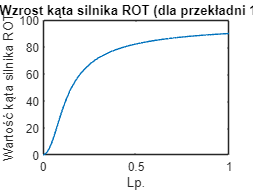



i=0;
kat_rakiety=1:n;
for z=1:n
    kat_rakiety(z)=i+kat(z);
    i=kat_rakiety(z);
end
plot(x,kat_rakiety)
title("Wzrost kąta silnika ROT (dla przekładni 1:1)")
xlabel("Lp.")
ylabel("Wartość kąta silnika ROT")

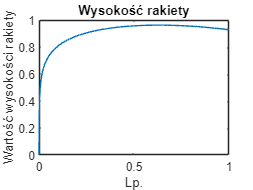


%Dla wysokości
plot(x,y)
title("Wysokość rakiety")
xlabel("Lp.")
ylabel("Wartość wysokości rakiety")

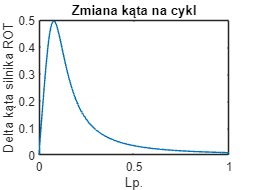



% Wynik końcowy
kat_e_rot = kat.*engine_multiplier_rot/360;
plot(x,kat_e_rot)
title("Zmiana kąta na cykl")
xlabel("Lp.")
ylabel("Delta kąta silnika ROT")

%ruch silnika rot
stepper_motor_list=1:n;
var = 0;
list=kat;
for i=1:(n-1)
    stepper_motor_list(i) = 0;
    while (list(i)*360/(engine_multiplier_rot))>=1
        stepper_motor_list(i)=stepper_motor_list(i)+1;
        list(i) = list(i)-360/(engine_multiplier_rot);
    end
    list(i+1) = list(i+1)+list(i);
end
stepper_motor_list(n) = 0;
stepper_motor_list

stepper_motor_list =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     1     0     0     0     1     0     0     0     1     0     0     0     1     0     0     1     0     0     1     0     1     0     0     1     0     0     1     0


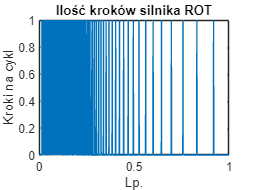

plot(x,stepper_motor_list)
title("Ilość kroków silnika ROT")
xlabel("Lp.")
ylabel("Kroki na cykl")

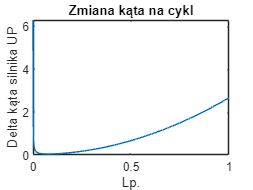


kat_e_up = dy.*engine_multiplier_up/360;
plot(x,kat_e_up)
title("Zmiana kąta na cykl")
xlabel("Lp.")
ylabel("Delta kąta silnika UP")

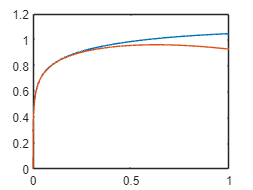


plot(x,((log10(6*(x+dx))+3.3)/3.805 - (6*(x+dx).^2/250)),x,y)

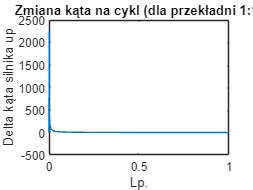


%ruch silnika up /////////////////////////////

list_y = 1:n;
list_y(1)=y(1);
for i = 2:n
    list_y(i) = y(i) - y(i-1);
end
list_y=list_y.*(engine_multiplier_up);
plot(x,list_y)
title("Zmiana kąta na cykl (dla przekładni 1:1)")
xlabel("Lp.")
ylabel("Delta kąta silnika up")




stepper_motor_list_2=1:n;
list=list_y;
for i=1:(n-1)
    stepper_motor_list_2(i) = 0;
    while list(i)>=1
        stepper_motor_list_2(i)=stepper_motor_list_2(i)+1;
        list(i) = list(i)-1;
    end
    while list(i)<=-1
        stepper_motor_list_2(i)=stepper_motor_list_2(i)-1;
        list(i) = list(i)+1;
    end
    list(i+1) = list(i+1)+list(i);
end
stepper_motor_list_2(n) = 0;
stepper_motor_list_2

stepper_motor_list_2 =            0        2267         633         370         263         204         166         141         122         107          97          87          79          73          68          63          59          55          52          49          47          45          42          41          38          38          35          35          33          32          31          30          29          28          27          26          26          25          24          24          23          22          22          21          21          21          20          19          19          19


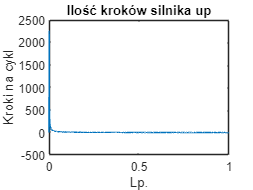

plot(x,stepper_motor_list_2)
title("Ilość kroków silnika up")
xlabel("Lp.")
ylabel("Kroki na cykl")

% //////////////////////////////////
% Zapis do pliku .txt
fileID = fopen('wynik.txt','w');
for i=1:n
    fprintf( fileID, '%d, %d, %d \r', i, stepper_motor_list_1(i), stepper_motor_list_2(i));
end
fclose(fileID);